% (y+x*log(y))*dx+(x^2/(2*y)+x+1)*dy=0

clear
% 1)
% y'=-(y+x*log(y))/(x^2/(2*y)+x+1)
syms x y(x) C
eqn=diff(y(x))==-(y+x*log(y))/(x^2/(2*y)+x+1)

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{y\left(x\right)+x\,\log\left(y\left(x\right)\right)}{x+\frac{x^{2}}{2\,y\left(x\right)}+1}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(\log\left(y\right)\,x^{2}+2\,y\,x+C_{12}+2\,y,y\right)$$

% solve(log(y)*x^2 + 2*y*x + 2*y == -C11, y)
eq1= log(y)*x^2 + 2*y*x + 2*y == C

$$eq1(x) = 2\,y\left(x\right)+x^{2}\,\log\left(y\left(x\right)\right)+2\,x\,y\left(x\right)=C$$


% 2)
syms x y
P(x,y)=y+x*log(y)

$$P(x, y) = y+x\,\log\left(y\right)$$

Q(x,y)=x^2/(2*y)+x+1

$$Q(x, y) = x+\frac{x^{2}}{2\,y}+1$$

chk1=diff(P,y)-diff(Q,x)

$$chk1(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = \frac{\log\left(y\right)\,x^{2}}{2}+y\,x+C\left(y\right)$$

% (log(y)*x^2)/2 + y*x + C(y)
dUy=diff(U,y)

$$dUy = x+\frac{x^{2}}{2\,y}+\frac{\partial }{\partial y}C\left(y\right)$$

% x^2/(2*y) + x + diff(C(y), y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-1$$

% diff(C(y), y) - 1
% C(y)=y+C1
eq2 = log(y)*x^2 + 2*y*x + 2*y == C

$$eq2(y) = \log\left(y\right)\,x^{2}+2\,y\,x+2\,y=C\left(y\right)$$

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = \frac{\log\left(y\right)\,x^{2}}{2}+y\,x+y$$

U=2*U

$$U = \log\left(y\right)\,x^{2}+2\,y\,x+2\,y$$

syms C
eq2=U==C

$$eq2 = \log\left(y\right)\,x^{2}+2\,y\,x+2\,y=C$$

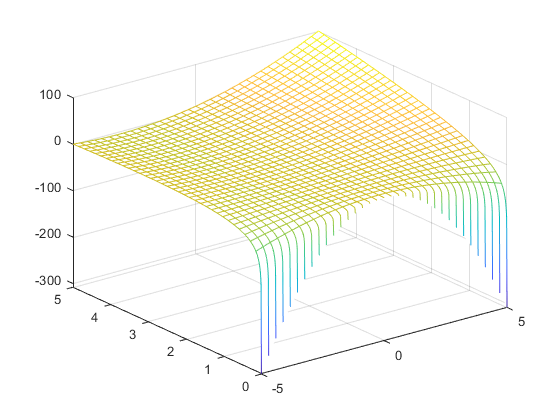

fmesh(U)